% clear;
data = load('resultadosCSV_5mhz.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27
n_max_start = 335
T           = 5e-9;

T_buscado = 1/(2*5e6)

T_buscado =      1.000000000000000e-07


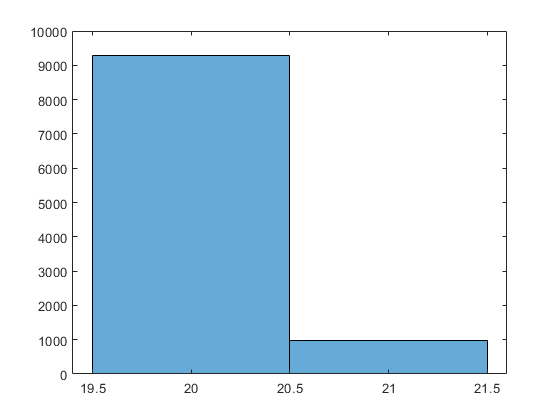

t_fino = (start-n_min_start)*tau_start - (stop-n_min_stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(coarse);

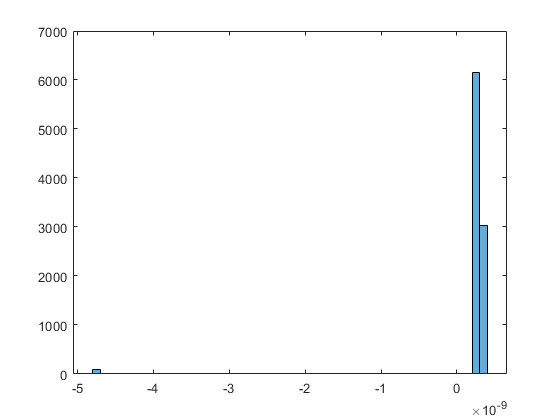


indices_20 = find(coarse==20);
indices_21 = find(coarse==21);

clf;
fino_20 = t_fino(indices_20);
histogram(fino_20);

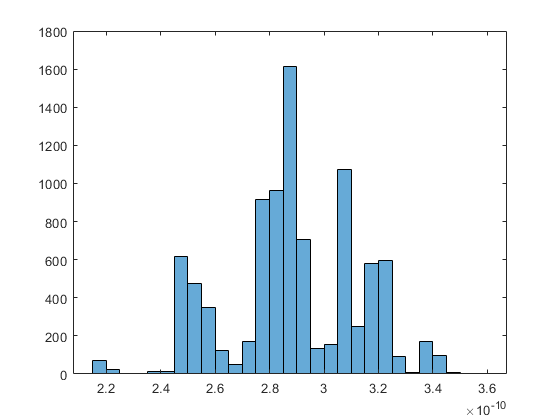

fino_20_malos = fino_20(fino_20<-3e-9);
fino_20_buenos = fino_20(fino_20>0);
histogram([fino_20_buenos; fino_20_malos+T])

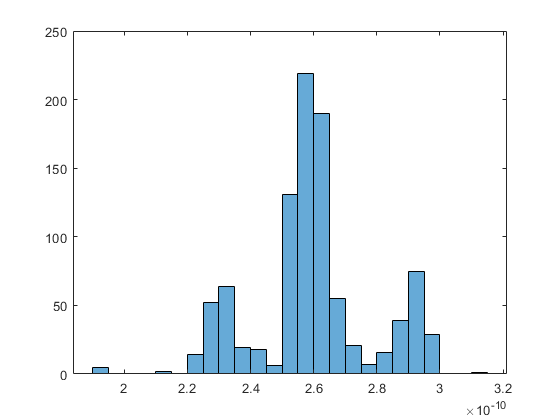


%%fino 21
%%Tenemos que restar un clock!!
fino_21 = t_fino(indices_21);
histogram(fino_21)

clf;
y = [fino_20_buenos; fino_20_malos+T; fino_21];
presicion = std(y)

presicion =      2.515971468062047e-11


media     = mean(y)

media =      2.861171347656258e-10


coarse_correcto = 20;
N = 100;
% Clear figure
clf;

% Data vectors
data = {fino_20_buenos, fino_20_malos+T, fino_21};

% Number of bins
N = 100;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = linspace(min_val, max_val, N+1);

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end
length(fino_21)

ans =    963


length(fino_20_malos)

ans =    107


length(fino_20_buenos)

ans =         9170


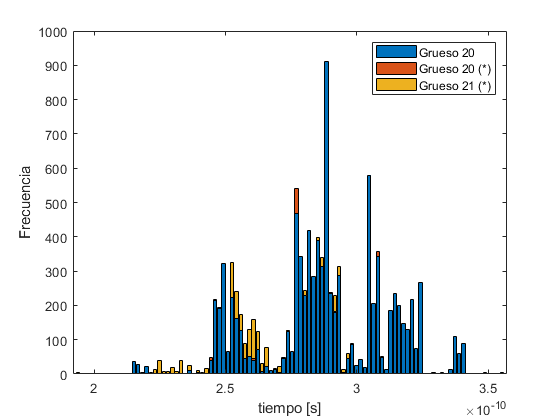

% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo [s]');
ylabel('Frecuencia');
legend({'Grueso 20', 'Grueso 20 (*)', 'Grueso 21 (*)'});
exportgraphics(gcf,'histograma_5M.eps');


format long
T_buscado

T_buscado =      1.000000000000000e-07


Tiempo_final = 20*T + media

Tiempo_final =      1.002861171347656e-07


error = Tiempo_final - T_buscado

error =      2.861171347656229e-10
